# Velocity Analysis

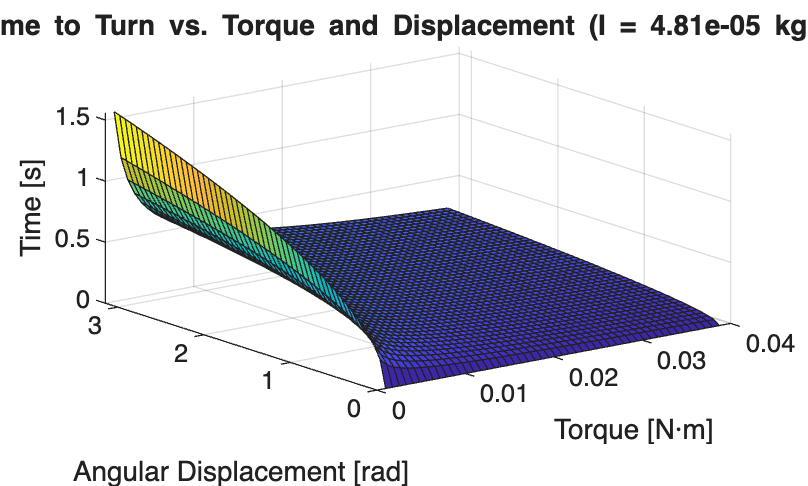


clc; clear all; close all;

% Pan Section Velocity and DC-motor Torque

% Pan Graph of Torque and Motion


I = 4.81*(10^-5);


torque = linspace(0.001,0.0387,50);
angle = linspace(0,pi(),50);


[T,theta] = meshgrid(torque,angle);


% Derived time equation "bang-bang" configuration

time = 4.*sqrt((I.*theta)./T);


surf(T,theta,time)


title(['Time to Turn vs. Torque and Displacement (I = ' num2str(I) ' kg·m^2)']);
xlabel('Torque [N·m]');
ylabel('Angular Displacement [rad]');
zlabel('Time [s]');



% Tilt Section Velocity and DC-motor Torque

% Tilt Graph of Torque and Motion


I = 4.81*(10^-5);


torque = linspace(0.001,0.0387,50);
angle = linspace(0,pi(),50);


[T,theta] = meshgrid(torque,angle);


% Derived time equation "bang-bang" configuration

time = 4.*sqrt((I.*theta)./T);


surf(T,theta,time)


title(['Time to Turn vs. Torque and Displacement (I = ' num2str(I) ' kg·m^2)']);
xlabel('Torque [N·m]');
ylabel('Angular Displacement [rad]');
zlabel('Time [s]');

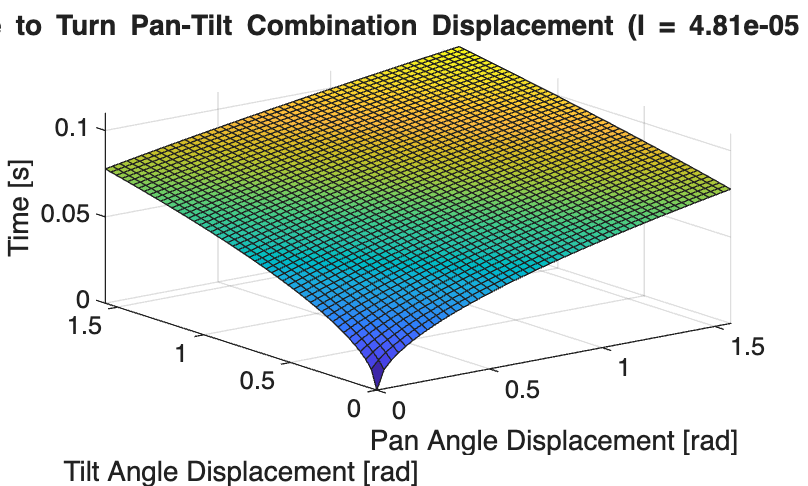



% Pan - Tilt Combination Graph


I = 4.81*(10^-5);


torqueA = 0.2;
torqueB = 0.2;


pan_angle = linspace(0,pi()/2,50);
tilt_angle = linspace(0,pi()/2,50);


[pan_angle,tilt_angle] = meshgrid(pan_angle,tilt_angle);


% Derived torque input
torque_pan = torqueA;
torque_tilt = torqueB - torqueA;


% Finding the max t for Pan and Tilt
tA = 4*sqrt((pan_angle.*I)/(torqueA));
tB = 4*sqrt(((I.*tilt_angle)+(I.*pan_angle))/(torqueB));


% Finding the max time taken for the process
time = max(tA,tB);


surf(pan_angle,tilt_angle,time)


title(['Time to Turn Pan-Tilt Combination Displacement (I = ' num2str(I) ' kg·m^2)']);
xlabel('Pan Angle Displacement [rad]');
ylabel('Tilt Angle Displacement [rad]');
zlabel('Time [s]');